# Train BERT Document Classifier

**ใช้ ****BERT ****กับ ****Text Classification**

ในตัวอย่างนี้เรามี **factory error reports** เป็นข้อความภาษาอังกฤษหรือไทย เช่น:

*"เครื่องผสมร้อนจัดผิดปกติ"*

*"ฟิวส์ขาดตอนสตาร์ทโรงงาน"*

*"วัสดุติดในเครื่องประกอบ"*

เราสามารถใช้ BERT เพื่อฝึกโมเดลให้: จำแนกข้อความแต่ละบรรทัดเป็นหมวดหมู่ เช่น:

*"ปัญหาทางไฟฟ้า"*

*"เครื่องจักรขัดข้อง"*

*"ระบบควบคุมขัดข้อง"*

**** ในตัวอย่างนี้ยังไม่ได้มีการ Preprocessing ข้อมูลหรือตัดคำ จัดเรียงภาษาไทยก่อน*

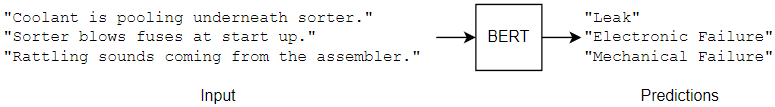

- **ตัวอย่างการใช้ใน ****MATLAB**

- สามารถใช้ Text Analytics Toolbox + Deep Learning Toolbox + BERT แบบ pre-trained ได้

## Load Training Data

Read the training data from the `factoryReports` CSV file. The file contains factory reports, including a text description and categorical label for each report.

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "factoryReports_thai";
opts.DataRange = "A2:E481";

% Specify column names and types
opts.VariableNames = ["Description", "Category", "Urgency", "Resolution", "Cost"];
opts.VariableTypes = ["string", "categorical", "categorical", "categorical", "double"];

% Specify variable properties
opts = setvaropts(opts, "Description", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Description", "Category", "Urgency", "Resolution"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("C:\Users\KantikaWongkasem\Documents\MATLAB\Examples\R2025a\deeplearning_shared\TrainBERTDocumentClassifierExample\factoryReports_thai.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
data

data = 480×5 table
                   Description                        Category          Urgency        Resolution        Cost 
    _________________________________________    ___________________    _______    __________________    _____

    "ชิ้นงานติดอยู่ในลูกกลิ้งของเครื่องสแกนเป็นครั้งคราว"     ความขัดข้องทางกล         ปานกลาง    ปรับตั้งเครื่องจักรใหม่         45
    "มีเสียงดังและสั่นสะเทือนจากลูกสูบของเครื่องประกอบ"    ความขัดข้องทางกล         ปานกลาง    ปรับตั้งเครื่องจักรใหม่         35
    "ไฟฟ้าดับขณะเริ่มเดินเครื่อง"                       ความขัดข้องทางไฟฟ้า       สูง         เปลี่ยนทั้งหมด            16200
    "คาปาซิเตอร์ในเครื่องประกอบไหม้"                  ความขัดข้องทางไฟฟ้า       สูง         เปลี่ยนชิ้นส่วน              352
    "มิกเซอร์ทำให้ฟิวส์ขาด"                           ความขัดข้องทางไฟฟ้า 

Convert the labels in the `Category` column of the table to categorical values and view the distribution of the classes in the data using a histogram.

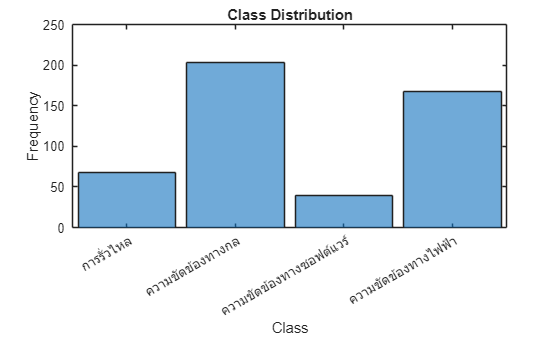

data.Category = categorical(data.Category);
figure
histogram(data.Category)
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

View the number of classes.

classNames = categories(data.Category);
numClasses = numel(classNames)

numClasses = 4

Partition the data into a training set and a test set. Specify the holdout percentage as 10%.

cvp = cvpartition(data.Category,Holdout=0.1);
dataTrain = data(cvp.training,:);
dataTest = data(cvp.test,:);

Extract the text data and labels from the tables.

textDataTrain = dataTrain.Description;
textDataTest = dataTest.Description;
TTrain = dataTrain.Category;
TTest = dataTest.Category;

figure
wordcloud(textDataTrain);

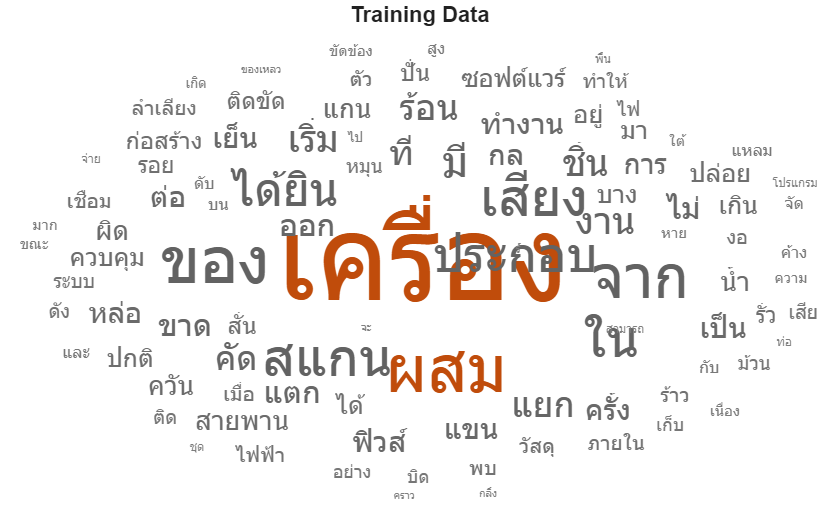

title("Training Data")

## Load Pretrained BERT Document Classifier

Load a pretrained BERT-Base document classifier using the `bertDocumentClassifier` function. If the Text Analytics Toolbox™ Model for BERT-Base Network support package is not installed, then the function provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click **Install**.

mdl = bertDocumentClassifier(ClassNames=classNames)

mdl =   bertDocumentClassifier with properties:

       Network: [1×1 dlnetwork]
     Tokenizer: [1×1 bertTokenizer]
    ClassNames: ["การรั่วไหล"    "ความขัดข้องทางกล"    "ความขัดข้องทางซอฟต์แวร์"    "ความขัดข้องทางไฟฟ้า"]


## Specify Training Options

Specify the training options. Choosing among training options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app.

- Train using the Adam optimizer.

- Train for 100 epochs.

- For fine-tuning, lower the learning rate. Train using a learning rate of 0.0001.

- Shuffle the data every epoch.

- Monitor the training progress in a plot and monitor the accuracy metric.

- Disable the verbose output.

options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    InitialLearnRate=0.0001, ...
    Shuffle="every-epoch", ...  
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Train Neural Network

Train the neural network using the `trainBERTDocumentClassifier` function. By default, the `trainBERTDocumentClassifier` function uses a GPU if one is available. Training on a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information about supported devices, see [GPU Computing Requirements](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainBERTDocumentClassifier` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

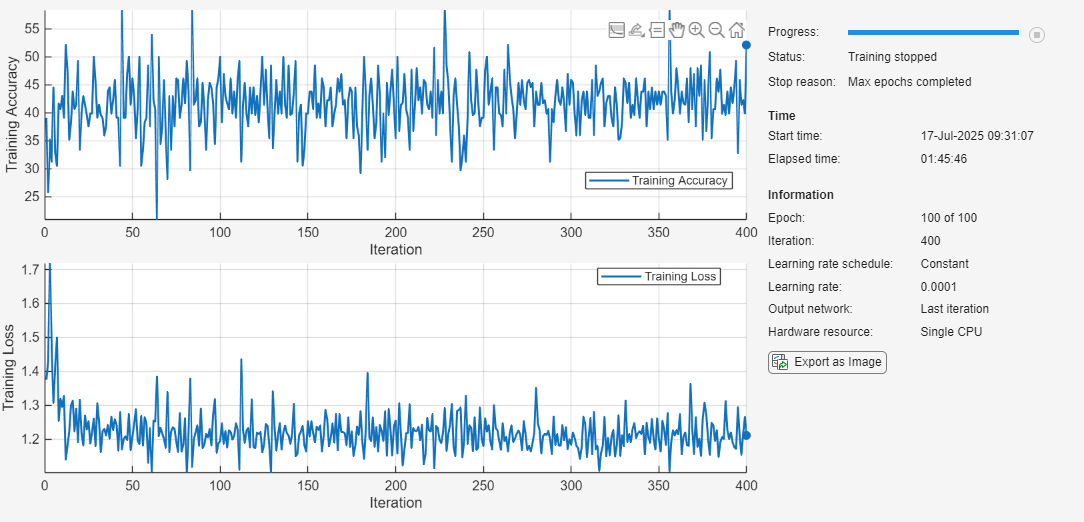

mymdl = trainBERTDocumentClassifier(textDataTrain,TTrain,mdl,options);

Load mdl model that we alredy trained

load Thaimdl.mat

## Test Neural Network

Make predictions using the test data.

YTest = classify(mymdl,textDataTest);

Visualize the predictions in a confusion matrix.

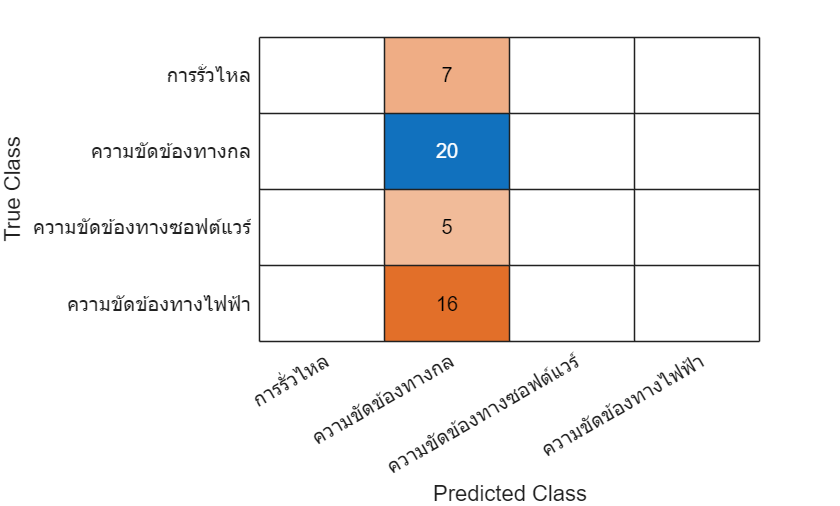

figure

confusionchart(TTest,YTest)

Calculate the classification accuracy of the test predictions.

accuracy = mean(TTest == YTest)

accuracy = 0.4167

## Make Predictions Using New Data

Classify the event type of new factory reports. Create a string array containing the new factory reports.

strNew = [
    "สายพานหยุดหมุน."
    "เครื่องคัดแยกทำให้ฟิวส์ขาดขณะเริ่มต้นการทำงาน."
    "มีเสียงโลหะกระทบกันดังมากจากเครื่องประกอบ."];
labelsNew = classify(mymdl,strNew)

labelsNew = 3×1 categorical array
     ความขัดข้องทางกล 
     ความขัดข้องทางกล 
     ความขัดข้องทางกล 


*Copyright 2025 The MathWorks, Inc.*